## **Tasks**

- Create an MPC closed-loop system in MATLAB to manoeuvre a quadcopter inside a constrained region.

- Write concise reports detailing your controller implementation and relevant design choices.

## **Summary**

In this coursework, you will implement a closed-loop MPC system in a provided software template. The controller should be designed to handle arbitrary constraint sets that take the form of a cuboid with elliptical cylinder walls, as shown by the example below.

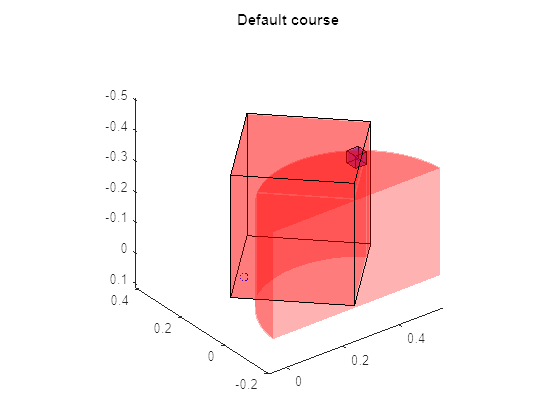

defaultCourse(1,2); 

%Figure 1: Plotting the default course for part 2

This will involve the quadcopter moving inside the defined region from a starting point to a target point without violating specified constraints. The flying robot should not hit any obstacle or leave a given space. For each test case, the parameters for the allowed space will be provided to your controller at the beginning of the run, along with the parameters defining each obstacle; the shapes will remain constant during the run.

## **Project Requirements**

### **Objectives**

The objective of this project is to move the quadcopter from the starting point to the target point without violating any physical or other constraints. 

- The time taken for the quadcopter to reach a target state (defined below) should not be more than the given parameter $T_t$. 

- The time for the quadcopter to be at the target should be for at least $T_e$ seconds.

- The total non-dimensional thrust $\Theta$ away from hover must not be more than the given parameter $\Theta_{max}$, where


$$     \Theta := \int_{0}^{T_f} { \sum_{i=1}^{4} {(u_{i}(t)-u_{ei})} }\, dt,$$


the final time $T_f:=T_t+T_e$, $u_{i}(t)\in[0,1]$ for $i=1,2,3,4$ are the inputs for each of the four propellers, and $u_{eq}=[u_{e1}\ u_{e2}\ u_{e3}\ u_{e4} ]^T$ is the input needed to maintain the quadcopter at hover (see below for more details). 

The input has been normalised by defining $u_i(t):=\omega_i^2(t)/\omega_{max}^2$, where $\omega_{max}$ is the maximum angular velocity of a rotor. The nominal value for $\omega_{max}^2$ can be found inside `UAV_Nominal_Parameters.mat` file along with other nominal parameters. 

Note: For the quadcopter, the thrust force $F_i$ for each propeller is assumed to be a linear function of $u_i$, which take on values in the interval $[0,1]$, and the square of the maximum angular velocity $\omega_{max}^2$. The units of $\Theta$ are therefore not Newtons, but appropriately normalised/scaled versions, hence $\Theta$ is non-dimensional, i.e. has no units.

The parameters will change between runs, but will be provided during the setup phase of each run and be constant for the entire run. Furthermore, the computational resources required by your controller should be minimised, i.e. you should aim to compute a control action in the least amount of time possible. 

### **Target **

The quadcopter will start with the geometrical center at the point $(x_s, y_s, z_s)$, and the target point will be located at the point $(x_t, y_t, z_t)$. Both the starting and the end points will change from run to run, but will be fixed during a single run. 

The quadcopter will be considered to be at the target point once the geometrical center of the quadcopter is within a given target cube having the side $2\epsilon_t$ and centred at the target point (i.e. $x_t - \epsilon_t \leq x(t) \leq x_t + \epsilon_t$ $\&$ $y_t - \epsilon_t \leq y(t) \leq y_t + \epsilon_t$ $\&$ $z_t - \epsilon_t \leq z(t) \leq z_t + \epsilon_t$ $\forall t \in [T_t,T_t+T_e]$). The above constraints on the state should be satisfied for at least $T_e$ seconds, i.e. for all $t\in[T_t,T_t+T_e]$.

Note that the inputs should ideally all settle at a constant value $u_{eq}$ needed to produce an amount of lift that will exactly balance the weight of the quadcopter for at least $T_e$ seconds. For this purpose you might wish to use the formula $4k\cdot \omega_{max}^2\cdot u_{ei}=m\cdot g$ where $k$ is a lift constant, $\omega_{max}$ is the maximum angular velocity of the motor, $m$ is the total mass of the quadcopter and $g$ is the gravitational constant. However, in practice, the exact values of $k$, $\omega_{max}$ and $m$ will be unknown. You will therefore either have to estimate these or use a different approach to stay in the target cube for $T_e$ seconds if there is uncertainty. Also note that the strating point and the box surrounding the target point can be located anywhere strictly inside the constrained region**.**

### **Constrained region**

The constraints are composed of two parts:

- One box obtained by extending with a height $h_c$ in the $z$ direction a rectangle at an arbitrary angle in the $xy$ plane,

- One or more elliptical cylinders removed from the box (for part 2 only).

The quadcopter is allowed to move anywhere inside the region, but must not leave it, with a sample region shown in Figure 1. The box constraint is defined by the 4 corners of a rectangle, which will be provided to you inside a 4x2 matrix of the form


$$c = \pmatrix{ x_1 & y_1 \cr x_2 & y_2 \cr x_3 & y_3 \cr x_4 & y_4 \cr }$$


along with a maximum height $h_{max}$ such that $-z(t) \in [0,h_{max}]$ is satisfied.The points in $c$ will be provided in a clockwise sequence as in Figure 2.

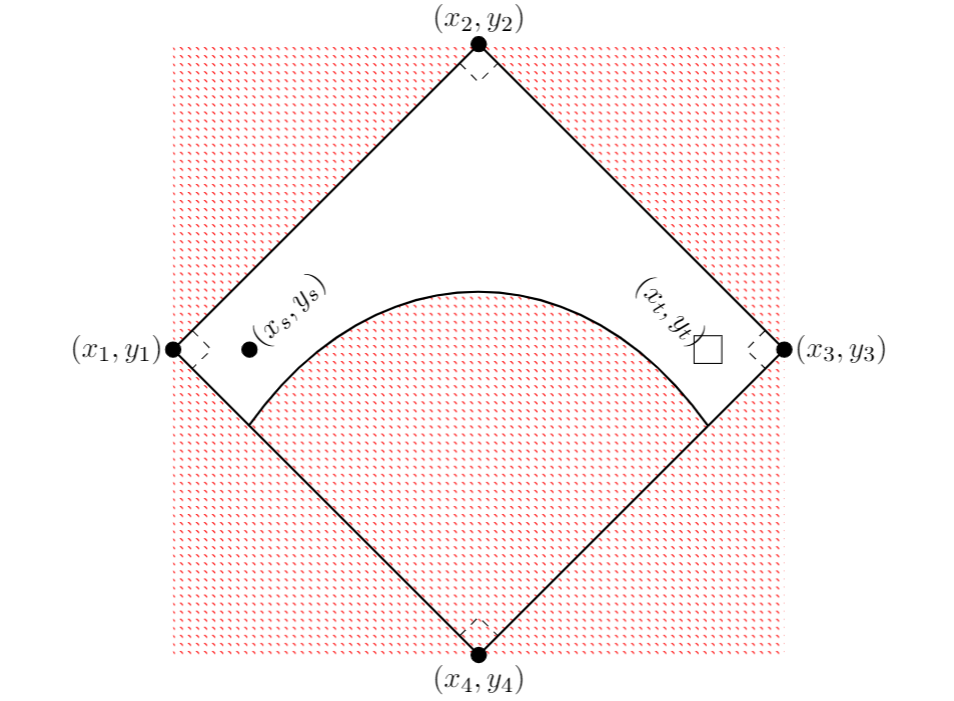

%Figure 2: Top view of the constrained region

Each elliptical cylinder will be defined by a quadratic constraint and a height. The quadcopter has to stay outside all elliptical cylinders. The quadratic constraint defining the vertical boundary of the cylinder will be given by

$\frac{( x - x_{c} )^2}{a^2} + \frac{( y - y_{c} )^2}{b^2} = 1$,

where $(x_{c}, y_{c})$ is the centre point for the ellipse and $a$ and $b$ are the axis lengths. The height $h$ of each elliptical cylinder, which extends in the negative $z$ direction from $-z=0
$ to $-z=h$, will be given. The ellipse data will be provided as a cell array of a struct containing fields for $a$, $b$, $h$, $x_{c}$ and $y_{c}$. The centre point $(x_{c},y_{c})$ of an ellipse may be located anywhere in the $xy$ plane, including inside or outside the rectangular region. 

Some additional notes:

- The constraints will always be defined such that a solution exists.

- The cube will be inside the region [-2.5,2.5]x[-2.5,2.5]x[0,5] (units in m).

- There will be a maximum of 10 elliptical cylinders (obstacles).

- The minimum space between obstacles will be 0.001 m.

- The interior of the target set will not intersect with any of the obstacles and will be entirely within the cube. 

### **Definitions**

#### **Equilibrium**

Obtaining equilibrium in the simulation run means that:

- The $x$, $y$ and $z$ position states of the quadcopter are within $\epsilon_{t}$ of the target point for all $t\in[T_t,T_t+T_e]$.

All comparisons are made using the infinity norm.

#### Successful Completion

Successful completion of a shape means that:

- The system is at equilibrium (as defined above) for all $t\in[T_t,T_t+T_e]$.

- The inputs remain in the interval $[0, 1]$ during the entire time interval $[0,T_t+T_e]$,

- The total thrust over $T_f:=T_t+T_e$ seconds is not greater than $\Theta_{max}$, i.e.  $\Theta \leq \Theta_{max}$.

- No constraints are violated over the whole time interval $[0,T_t+T_e]$ (this includes staying inside the given box and not hitting any obstacles).

The marking for the simulation component is done in 2 distinct steps:

- Successful completion of the default shape.

- Successful completion of an unseen selection of other generated shapes.

## **Approach**

### **Physical System**

This coursework is based on a quadcopter. A suitable model can be derived by referring to the `QuadrotorStateEquationsDerivation.mlx` file which is provided to you in MATLAB Drive, or using any other method that you might deem more suitable. Note that all distances will be measured in meters and all angles will be measured in radians. The quadrotor can be assumed to be a point mass located at the geometrical center and all constraints must be satisfied only by the geometrical center.

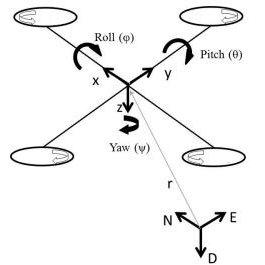

%Figure 3: Coordinate system and states for the quadrotor

Each angle is measured in an Earth-fixed coordinate system/frame of reference, with $\phi$ being the roll angle measuring the rotation about $x$- axis, $\theta$ representing rotation about the $y$-axis and is referred to as pitch angle and $\psi$ is the yaw angle representing the rotation about the $z$ axis  (as shown in Figure 3). Angular velocities around $x, y, z$ axes are denoted by $p,q,r$. The motors controlling the rotational speed of the four propellors can only accept inputs in the range $[0, 1]$. The coordinates are denoted by $X, Y, Z$ and $U, V, W$ are the velocities in the $x, y, z$ directions respectively.

The model is provided with nominal parameters, and during marking variations of up to 10% will be added to each parameter, i.e. there will be a mismatch between the model you use to design your controller and the test system (for example in total mass, lift constant, arm lengths, maximum angular velocity etc.). 

### **Controller framework**

You will be responsible for writing `MATLAB` functions for this project. Note that this coursework will be marked using the most up to date version available on MATLAB Online available at the start of term. The architecture that you will be provided is shown in Figure 4. 

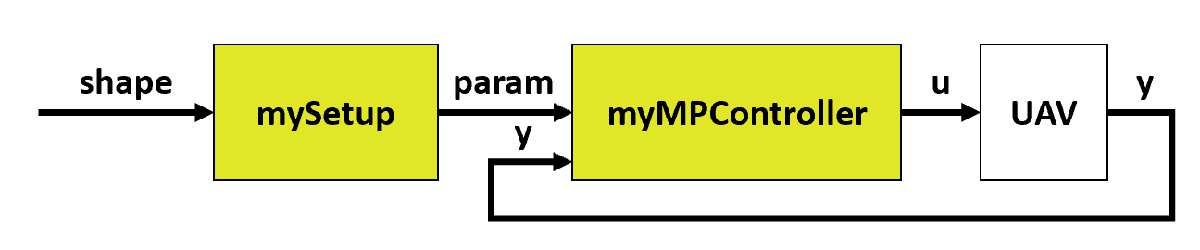

%Figure 4: Block diagram of the complete software framework system. Yellow blocks are the user-editable functions.

This framework is designed to allow for the implementation of a Model Predictive Controller on the unmanned air vehicle (UAV) system. The controller blocks (shown in yellow in Figure 4) are implemented inside MATLAB functions, which are then connected to a nonlinear model of the UAV. Your function in this assignment have access to any MATLAB function provided by the Control toolbox and MATLAB itself. However, note you are **not allowed** **to use functions from the Model Predictive Control** **toolbox or Optimization toolbox **for completing some parts of this assignment (as it will be explained later).

#### Files

The framework is composed of the following files provided on MATLAB Drive:

- CW_description.mlx

- FunctionTemplete.m

- defaultCourse.m

- testMyDesign_Nonlinear.m

- HelperFunctions/analyzeCourse.p

- HelperFunctions/extractFunctions.m

- HelperFunctions/plotCourse.m

- Model/UAV_nl_model.p

- Model/UAV_NominalParameters.mat

- Model/QuadrotorStateEquationsDerivation.mlx

**CW_description.mlx **provides general instructions about completing and submitting the coursework. You are advised to read this carefully before attempting to solve the coursework. Inside **QuadrotorStateEquationsDerivation.mlx** you can find a full derivation of a dynamics model that you can use. The main design must be done inside **FunctionTemplate.m**, which contains a blank template for the required functions. The course being tested against can be modified by changing the parameters inside the **defaultCourse.m** function to give new shapes/parameters to use. The functions inside the **HelperFunctions** and **Model** directories should not be modified.

#### Using the framework

To begin using the framework, download the necessary files to your local computer and ensure that all the files are on your MATLAB path. To design the controllers, modify the functions provided in the **FunctionTemplate.m** file. Do not modify the input or output variable declarations of the functions, including the size of the variables. Only make changes to the functions inside the template file, since all other locations (e.g. inside the file with the function's name) will be overwritten every time you use the **testMyDesign_Nonlinear** script.

You can test your design on an unknown nonlinear ODE model of the UAV using the **testMyDesign_nonlinear.m** script. This script will automatically load the default course and the model parameters, run a simulation of the closed-loop system, and display the resulting UAV path, constraints, and settling time information. You can also look inside **testMyDesign_Nonlinear.m **to see the parameters that will be varied. Your controller can be debugged by placing debug points inside the **FunctionTemplate.m** file on the appropriate line, and then using the MATLAB debugger. Note that the debugger will open the file with the function's name instead of the **FunctionTemplate.m** file when it is run. 

#### Template Function

The controller is composed of two functions:

- mySetup

- myMPController

#### mySetup

    This function is where you can implement any controller generation/design tasks (e.g. matrix generation, gain programming, constraint generation, etc.). This function gets one input variable that describe the shape being tested on: `shape`. This variable is a struct that contains the following fields:

- `constraints` - The rectangle and ellipses for the current course

- `eps_t` - The target point tolerance

- `target` - The target point

- `start` - The start point

- `ThetaMax` - The maximum amount of (nondimensional) integrated thrust allowed above the hover thrust ($\Theta_{max}$)

- `Tt` - Time taken for the quadcopter to reach a target state

- `Te` - Time duration for which the quadcopter needs to remain at the target state

This function returns one variable, `param`. This variable is a MATLAB structure for which you define the fields. This structure will be passed to the controller function, so variables set inside this structure can be used inside your controller functions. **You have to choose a sampling time **$T_S$** for the controller functions to run.** You can do this by setting the `Ts` variable to the desired sampling interval in seconds inside the `param` struct before returning from this function.

#### myMPController

    You will be responsible for writing the main body of the controller function that run inside the architecture shown in Figure 4. The block will have a fixed number of two inputs and one output. First input variable is the parameters struct `param` which was defined in the setup function **mySetup**. The value of this variable is given by you during the intial setup phase as described above and will remain constant for the entire simulation. **myMPController** function gets as second input $y$ which represents the measured state output from the UAV model dynamics. This block is designed to contain your MPC implementation. The block has one output, which is the 4x1 control signal $u$ that is given to the UAV in the next sample period. The control signal has the components: $u = \left[\matrix{u_1 & u_2 & u_3 & u_4}\right]^{T}$. Use persistent variables if you would like to keep values between the time steps of the controller.

**Note: The simulation will run with a computational timeout of 90 seconds if it were to run on MATLAB Online.** This means that after either 90 seconds of real-world computation time or the $T_{f}:=T_t+T_e$ seconds of simulation time has elapsed, the simulation will terminate and the results up to that point will be used. This should be more than enough time for you to successfully complete all shapes if you have a good design and aimed to reduce the computational requirements of your controller. Also note that the computational timeout includes both the setup function and the controller function.

### **Submission**

You will be submitting your functions on MATLAB Grader for this assignment. MATLAB Grader does not do any marking of your design. MATLAB Grader will only test to make sure your controller functions will execute, and that you are using the correct input and output sizes. Grader will supply a representative input, in order to catch MATLAB programming errors (like compilation errors), but will not actually perform any validation of your design. The tests on MATLAB Grader will utilize the latest version of MATLAB to test your code, so you are responsible for testing your own code on the correct version before submission. No marking will be done on MATLAB Grader, and the tests on it have no impact on the final marks your controller will receive. 

You should submit two sets of code on Grader:

- One set of code should use functions from the Model Predictive Control Toolbox. You are *not* allowed to use any functions from the Optimization Toolbox for this code. The score for this code will make up 40% of your software score.

- One set of code should use functions from the Optimization Toolbox. You are *not* allowed to use any functions from the Model Predictive Control Toolbox for this code. The score for this code will make up 60% of your software score.

**NOTE: There is a limit of 60,000 characters for entering your controllers into the MATLAB Grader submission field.**

## Part 1

### Overall scoring

Part 1 of this coursework is worth 15 points with the breakdown given below. 

#### **Software (5 points)**

- Default shape (2 points)

- Other shapes (3 points)

#### Report (10 points)

See the rubric on OneNote.

### **Simulation marking**

The data for the default shape, starting point, target point and tolerance can be found in `defaultCourse.m`

Note the following:

- **No **elliptical cylinders will be given as constraints in Part 1. However, there will be elliptical cylinders  given as constraints in Part 2. 

- There are **no** perturbations to the model parameters in Part 1. However, there will be perturbations to the model parameters in Part 2. 

- Points will be awarded for the successful completion of the default shape (with successful completion as defined above). 

- The remaining unseen shapes will be generated by varying the size of the box (e.g. narrowing it, rotating it, etc.), moving the starting and target points, changing the size of the target set, etc.

### Report

You are required to write a short report detailing your solution to this assignment. This report must not be more than **1 page (2-column format)** in length, including references, and cannot contain any appendices.** Any report longer than 1 page of PDF or containing appendices will receive zero marks, without exception.** A LaTeX template will be provided for you to use when writing the report. You must use this template, and you are not allowed to modify it. If you utilize a technique from the literature that was not discussed in lectures, you must provide a citation to the paper using the IEEE reference style.

The report should describe your solution to this project. This description can assume the reader has a basic knowledge of MPC and the contents of the course; so it should focus on how you applied the material from the course to the project. The report must also answer the following questions:

- How did you include the system dynamics in the optimal control problem?

- How did you formulate the constraints in the optimal control problem? 

- How did you choose the cost function in the optimal control problem?

- What did you do to make sure your controller can handle unseen courses/shapes other than the default course/shapes?

- What did you do to minimise computational effort?

## Part 2

### Overall scoring

Part 2 of this coursework is worth 35 points with the breakdown given below. 

#### **Software** component (15 points)

- Default shape (5 point)

- Other shapes (10 points)

#### Report (20 points)

See the rubric on OneNote.

### **Simulation marking**

The data for the default shapes, starting point, target point and tolerance can be found in `defaultCourse.m`

- **Important: Elliptical cylinders will given as constraints.**

- **Important: The model parameters will be perturbed within 10% of their nominal value at the start of the simulation, and remain constant throughout. **

- Points will be awarded for the successful completion of the default shape (with successful completion defined in the "Definitions" section). 

- The remaining shapes will be generated by varying the size of the box (e.g. narrowing it, rotating it, etc.), changing the number, position and shape of one or more elliptical cylinders, moving the starting and target points, changing the size of the targey sey, and perturbing the model parameters/inputs.

### Report

You are required to write a short report detailing your solution to this assignment. This report must not be more than **2 page (2-column format)** in length, including references, and cannot contain any appendices.** Any report longer than 2 pages or containing appendices will receive zero marks, without exception.** A LaTeX template will be provided for you to use when writing the report. You must use this template, and you are not allowed to modify it. If you utilize a technique from the literature that was not discussed in lectures, you must provide a citation to the paper it appears in using IEEE reference style. You should also cite your report from Part 1, if appropriate and necessary, using the IEEE style for a report.

The report should describe your solution to this project. This description can assume the reader has a basic knowledge of MPC and the contents of the course; so it should focus on how you applied the material from the course to the project. The report must also answer the following questions:

- How did you include the system dynamics in the optimal control problem?

- How did you formulate the constraints in the optimal control problem? 

- How did you choose the cost function in the optimal control problem?

- What did you do to make sure your controller can handle unseen courses/shapes other than the default course/shapes?

- What did you do to make your controller robust to uncertainties?

- What did you do to minimise computational effort?

You should also point out and describe any method(s) that you did not implement in Part 1, but which you implemented in Part 2. 